# **Interpolazione e Smoothing : Fitting di Dati**

Questo documento mira ad illustare esempi d'utilizzo significativi per problemi di **interpolazione e smoothing** utilizzando le funzioni Matlab.

# Interpolazione

## **Tool di interpolazione**

Nella seguente sezione viene presentato un tool nel quale esplicitando il numero di punti sul grafico viene mostrato il confronto tra le varie tipologie di interpolazione messe a disposizione dal `MATLAB`. Si può scegliere il tipo di interpolazione desiderato tramite menù a tendina**.**

**Per eseguire il tool, basta digitare nella Command Line del MATLAB : *****"GUI_Interpol"***

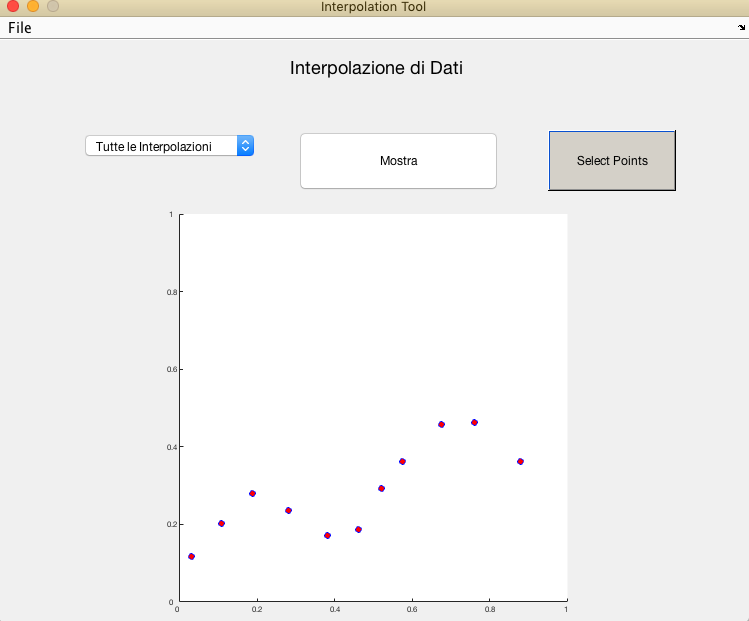

Da come si nota dalla figura in sovraimpressione, il tool presenta i seguenti componenti:

- Pulsante di selezione dei punti

- Pulsante di esecuzione del metodo di interpolazione (Mostra)

- Menù a tendina della scelta del metodo

Cliccando sul pulsante di selezione dei punti è possibile:

- Selezionare con il tasto sx del mouse il numero di punti di coordinata x crescente (da sx verso dx)

- Prima di completare la selezione specificare con il tasto dx del mouse l'ultimo punto di coordinata x più grande

Una volta effettuata la selezione dei punti, scegliere il metodo di interpolazione desiderato e cliccare sul pulsante "Mostra". Di seguito mostriamo alcuni esempi del tool:

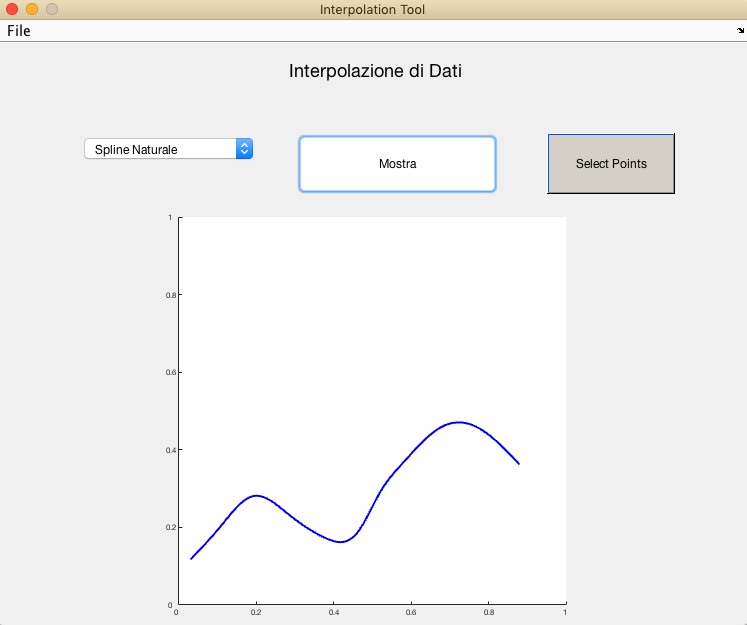

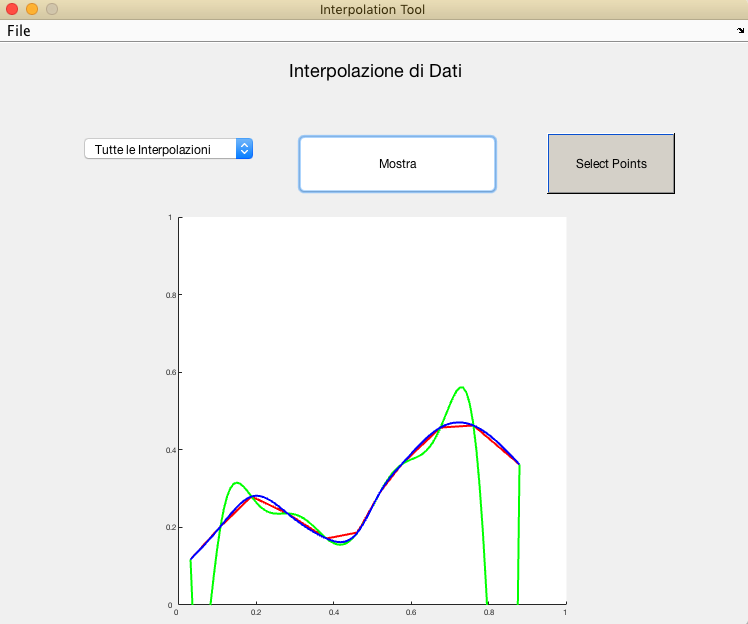

Dall'ultima immagine possiamo notare che il metodo di `interpolazione polinomiale` (rappresentato dalla curva in verde) è meno accurato data la sua natura oscillante. Per questo, si preferisce in tante applicazioni, usare il metodo` spline` (rappresentato dalla curva in blu).

## Esempi di applicazione dei metodi di interpolazione

Viene preso in considerazione un dataset contenente dati annuali dal 1922 al 1999 sui `Rendimenti Azionari Danesi` escludendo rendimenti non specificati (indicati come NaN). Da queste informazioni viene ricavato un andamento preciso attraverso i metodi di interpolazione.

**Il seguente codice mostra l'andamento del valore di rendimento annuo "DY"**

load Data_Danish.mat
%Esclusione dati non specificati
rvi = find(~isnan(Data(:,1)));
anno = dates(rvi);
rendita_anno = Data(rvi,1);


***Mostriamo l'andamento del rendimento annuo con l'utilizzo del metodo di interpolazione polinomiale*** 

periodo = 1922:0.1:1999;
p=polyfit(anno,rendita_anno,length(rendita_anno)-1);  %pol.int.  grado 5

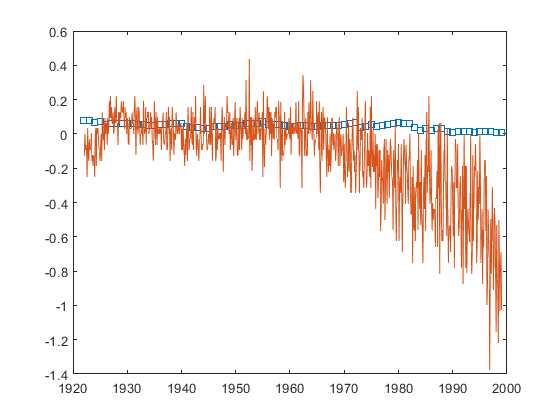

f=polyval(p,periodo);
plot(anno,rendita_anno,'s',periodo,f)

Si nota che il polinomio interpolante non è un buon modello per descrivere il fenomeno che ha originato i dati. Infatti i polinomi di grado elevato oscillano fortemente tra i dati. Matlab per avvertire l'utente di questa condizione genera un warning se usiamo polinomi di grado maggiore di 10.

Poichè l'uso dei polinomi è facilmente gestibile via software , ma la funzione interpolante ha uno stretto legame tra grado e numero di nodi si utilizza la tecnica dell'interpolazione a tratti.

***Mostriamo l'andamento del rendimento annuo con l'utilizzo del metodo di interpolazione polinomiale a tratti***

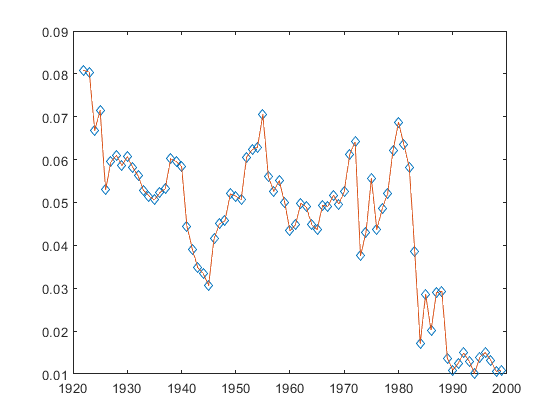

pt=interp1(anno,rendita_anno,periodo);
plot(anno,rendita_anno,'d',periodo,pt)

Questo modello è efficiente ed accurato, inoltre ha una convergenza migliore rispetto all'interpolazione polinomiale, infatti più nodi prendo meglio si approssima il modello. Però il problema di questo modello è che la funziona ha punti spigolosi, ma a noi interessa avere una curva liscia e senza spigoli.

**Mostriamo l'andamento del rendimento annuo con l'utilizzo del metodo di Spline. **

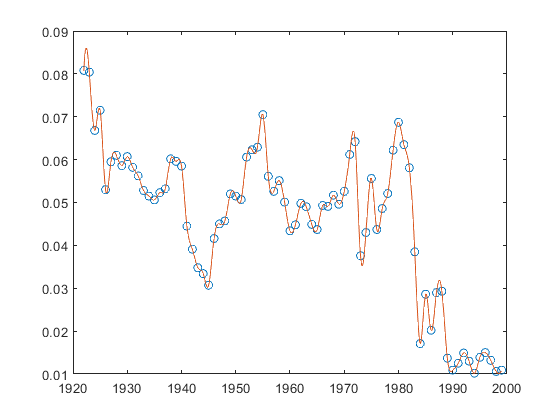

sp = spline(anno,rendita_anno);
periodo = 1922:0.1:1999;
%La funzione ppval restituisce un grafico a partire dai valori restituiti da spline
graf = ppval(sp,periodo);
plot(anno,rendita_anno,'o',periodo,graf)

Come si nota dal grafico, la curva è diventata liscia e senza spigoli.

Analizzando il problema trattato da questo modello si nota che  il rendimento annuale danese è diminuito vertiginosamente dagli inizi degli anni 80 fino alla prima metà, questo calo drastico si è propagato anche negli anni successivi.

**Si mostra l'andamento utilizzando un metodo di interpolazione Spline Cubica Naturale.**

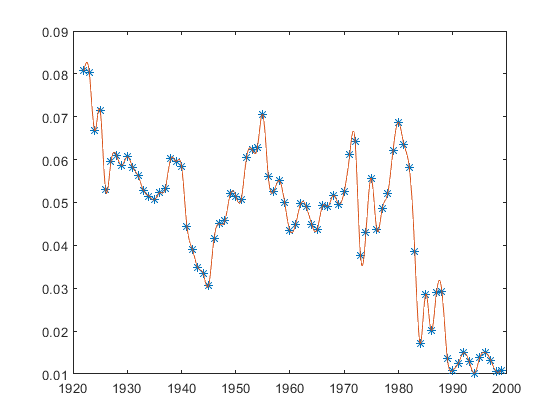

sp = csape(anno,rendita_anno,'second');
graf = ppval(sp,periodo);
plot(anno,rendita_anno,'*',periodo,graf)

## Interpolazione Spline e utilizzo della Derivata

In questa sezione si mostrano degli esempi sulla spline Interpolante e come questa permette di rappresentare la derivata di una funzione.

Il codice seguente mostra le differenze tra una funzione, la rappresentazione Spline Not-A-Knot e Cubica Naturale**. **

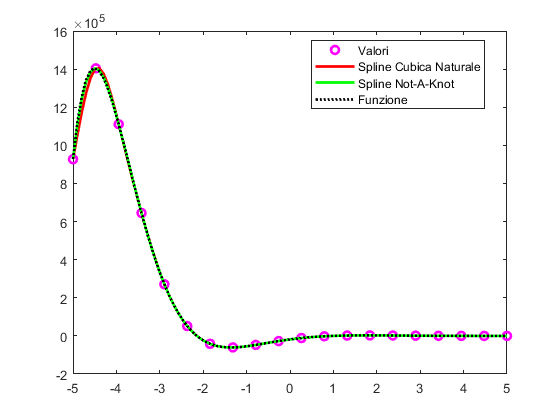

x1 = linspace(-5,5,20); %Asse x su 20 punti
x2 = linspace(-5,5,100); %Asse x su 100 punti
% Funzione
fx1 = exp(-x1 + 10).*cos(x1 + 10);
fx2 = exp(-x2 + 10).*cos(x2 + 10);
% Rappresentazione Spline Not-A-Knot
pp1 = spline(x1,fx1);
sp1 = ppval(pp1,x2);
% Rappresentazione Spline Cubica Naturale
pp2 = csape(x1,fx1,'second');
sp2 = ppval(pp2,x2);
plot(x1,fx1,'om',x2,sp2,'r',x2,sp1,'g',x2,fx2,':k','LineWidth',2);
legend('Valori','Spline Cubica Naturale','Spline Not-A-Knot','Funzione','Location',"best");

Da come si può notare la Spline Not-A-Knot risulta molto più accurata rispetto alla Cubica Naturale.

**Si confronta la derivata analitica della funzione con la sua rappresentazione Spline ottenuta tramite la funzione "fnder".**

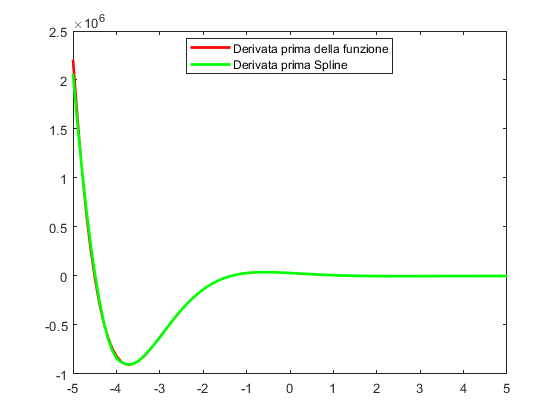

% Utilizzo della derivata
y_primo = -exp(-x2+10).*(sin(x2+10)+cos(x2+10));
sp_derivata = fnder(pp1,1);
pp3 = ppval(sp_derivata,x2);
plot(x2,y_primo,'r',x2,pp3,'g','LineWidth',2);
legend('Derivata prima della funzione','Derivata prima Spline','Location','best');

Un ulteriore conferma la otteniamo con la derivata, nonostante ciò `fnder` risulta molto più accurata rispetto alla derivata analiticamente calcolata.

# Interpolazione bidimensionale e Smoothing di dati

## **Interpolazione di curve parametriche**

Fino a questo momento abbiamo visto come le tecniche di interpolazione polinomiale permettano di valutare l’andamento di funzioni nelle quali i punti sono posti in serie. Se la funzione da interpolare è parametrica e l ’insieme dei suoi punti disegna  nello spazio delle curve chiuse, non è possibile sfruttare direttamente i metodi fin qui analizzati, si userà la spline interpolante parametrica.

Interpolazione della spirale

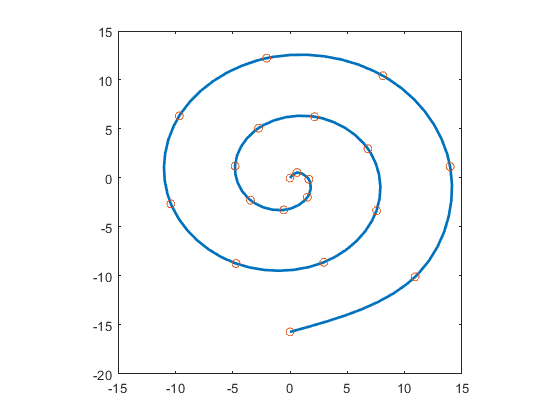

%interpolazione spirale

t=linspace(0,5*pi,20);
x =t.*sin(t);y =t.*cos(t);
points=[x;y];
fnplt(cscvn(points)); hold on,
plot(points(1,:),points(2,:),'o')
axis square

figure

Si mostra l'interpolazione del cardioide

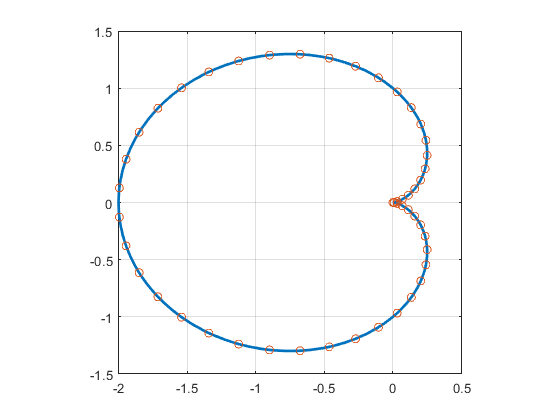

%Cardiode
t=linspace(0,2*pi,50);
x=cos(t).*(1-cos(t)); y=sin(t).*(1-cos(t));
points=[x;y];
fnplt(cscvn(points)); hold on,
plot(points(1,:),points(2,:),'o')
grid on
axis square

figure

Interpolazione curva della farfalla

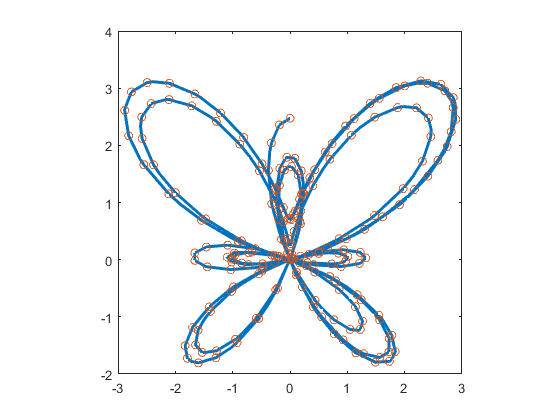

%interpolazione curva della farfalla
t=linspace(0,5*pi,200);
x = sin(t).*(exp(cos(t)) - 2*cos(4*t) - sin(t / 12).^5);
y = cos(t).*(exp(cos(t)) - 2*cos(4*t) - sin(t / 12).^5);
points=[x;y];
fnplt(cscvn(points)); hold on,
plot(points(1,:),points(2,:),'o')
axis square

figure

**Curva di Laporte**

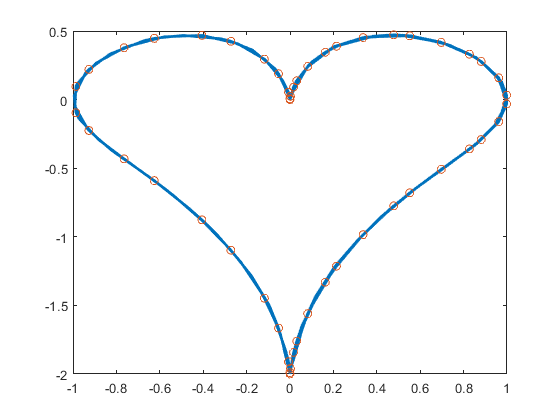

%interpolazione curva di Laporte
t=linspace(0,5*pi,50);
x=sin(t).^3;
y=cos(t)-cos(t).^4;
points=[x;y];
fnplt(cscvn(points)); hold on,
plot(points(1,:),points(2,:),'o')

## Estrapolazione e Previsione dei Dati

Il Matlab mette a disposizione una particolare funzione` fnxtr` che consente di prevedere il comportamento di alcune funzioni. In alcuni casi,  abbinata all'interpolazione spline consente di dare una rappresentazione di una funzione quasi uguale a quella reale.

In questa sezione, testiamo il comportamento della funzione degli errori complementare `erfc` attraverso l'utilizzo del comando `fnxtr` e confrontiamo il risultato con una sua rappresentazione attraverso un polinomio di secondo grado.

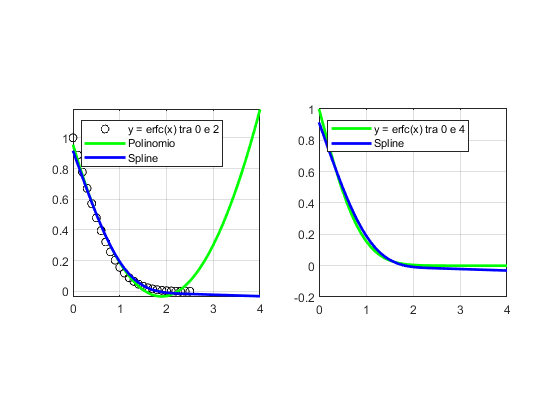

clear
x = 0:0.1:2.5;
y =erfc(x); % Funzione Errore tra 0 e 2
% Utilizzo della funzione fnxtr in abbinata alla Spline Cubica Naturale
result = fnxtr(csaps(x,y,.85));
poli = polyfit(x,y,2);
x1 = 0:0.1:4;
f = polyval(poli,x1); %Polinomio di secondo grado
ys = ppval(result,x1); %Spline Cubica Naturale + fnxtr
y1 =erfc(x1); % Funzione Errore Complementare tra 0 e 4
subplot(1,2,1)
primo = plot(x,y,'ko',x1,f,'g',x1,ys,'b'); 
grid
legend('y = erfc(x) tra 0 e 2','Polinomio','Spline','Location','northwest')
axis square
subplot(1,2,2)
secondo = plot(x1,y1,'g',x1,ys,'b');
grid
legend('y = erfc(x) tra 0 e 4','Spline','Location','northwest')
axis square
primo(2).LineWidth = 2;
primo(3).LineWidth = 2;
secondo(1).LineWidth = 2;
secondo(2).LineWidth = 2;

Da come si può notare, nel primo grafico il comportamento del `polinomio` perde non appena si supera un valore di x=2 mentre la `spline` segue l'andamento della funzione` erfc `differendo leggermente da quest'ultima.

**La differenza tra la funzione erfc  con la spline ed il polinomio può essere mostrato attraverso un residuo**

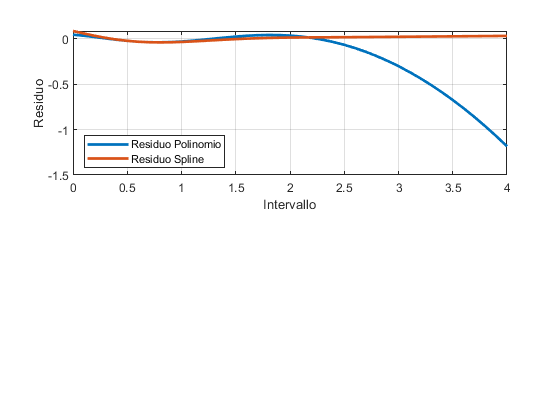

resid_polinomio = y1 - f;
resid_spline = y1 - ys;
vettore = [resid_polinomio' resid_spline'];
subplot(2,1,1)
p = plot(x1,vettore);
xlabel('Intervallo')
ylabel('Residuo')
legend('Residuo Polinomio','Residuo Spline','Location','southwest')
grid;
p(1).LineWidth = 2;
p(2).LineWidth = 2;

Il residuo misura lo scostamento dalla curva interpolante da quella vera. Tale scostamento è elevato per la curva interpolante polinomiale mentre è quasi nullo per la spline. 

## Interpolazione di Curve Bidimensionali

L'impiego dei metodi di interpolazione risulta molto efficiente quando si devono adoperare funzioni e oggetti in più dimensioni. Di seguito mostriamo alcuni esempi sull'utilizzo dell'interpolazione Spline su curve bidimensionali.

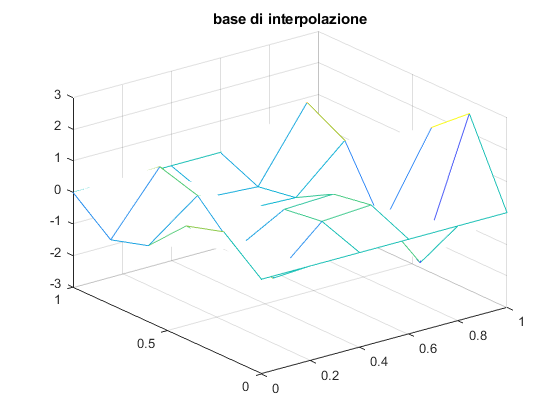

% interp. Bidimensionale 
%griglia
[x,y]=meshgrid(0:0.2:1,0:0.2:1);
z=exp(x).*cos(4*pi*x).*sin(2*pi*y);
%griglia in cui valutare l’interpolante
xi=0:0.05:1;yi=0:0.05:1;
[xf,yf]=meshgrid(xi,yi);
%plot dei punti dati e quelli ottenuti con l’int.
figure
mesh(x,y,z), title('base di interpolazione');

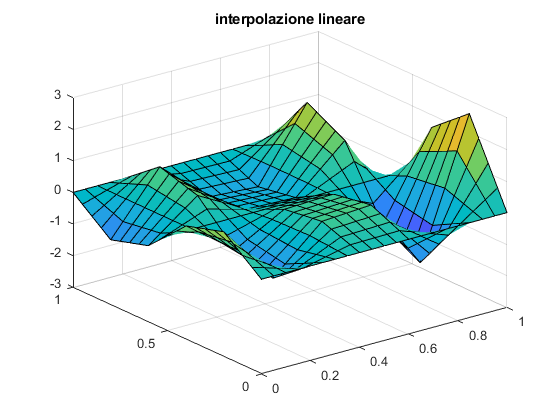

figure
zi=interp2(x,y,z,xf,yf,'linear');
surf(xf,yf,zi),title('interpolazione lineare');

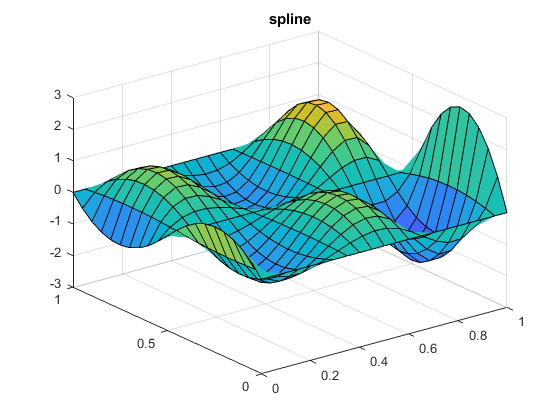

figure
zi=interp2(x,y,z,xf,yf,'spline');
surf(xf,yf,zi),title('spline');

Ci mettiamo nell'ipotesi in cui la funzione z mostrata in seguito sia affetta da rumore, notiamo che attraverso uno `smoothing di superficie `si può ricostruire la curva di partenza priva di rumore.

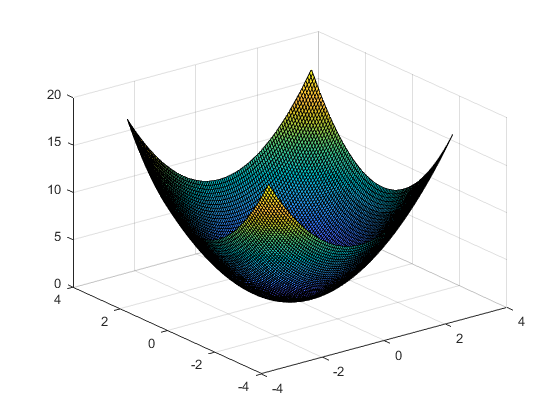


 N = 3.0;
x=linspace(-N, N);
y=x;
[X,Y]=meshgrid(x,y);
z=X.^2+Y.^2;
surf(X,Y,z);

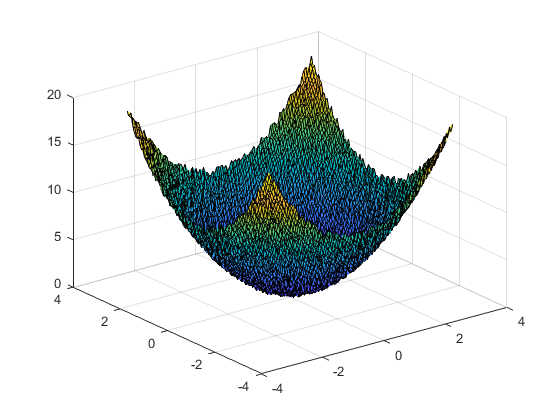

noisy = z+(rand(size(z))+.5);
figure
surf(X,Y,noisy)

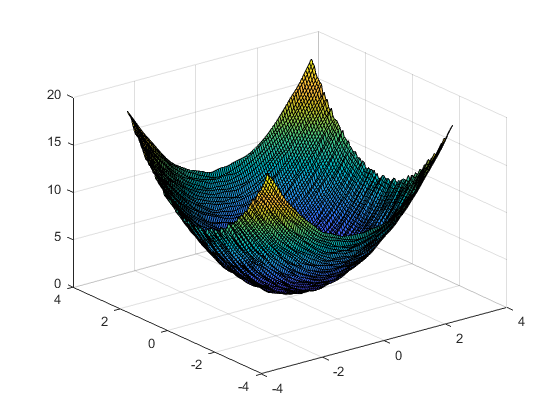

pp = csaps(x,noisy,.996);
smooth=ppval(pp,x);
figure
surf(X,Y,smooth);

Come si nota dalla figura, applicando lo smoothing di superficie si riesce a recuperare (seppure con qualche increspatura) la curva di partenza.

## **Paraboloide Ellittico**

Di seguito è mostrata una parametrizzazione del paraboloide.

[u,v] = meshgrid(-1:0.1:1);
x = 5.*cosh(u).*cosh(v);
y = 5.*cosh(u).*sinh(v);
z = 3.*sinh(u);

Si ottiene inizialmente una superficie non regolare

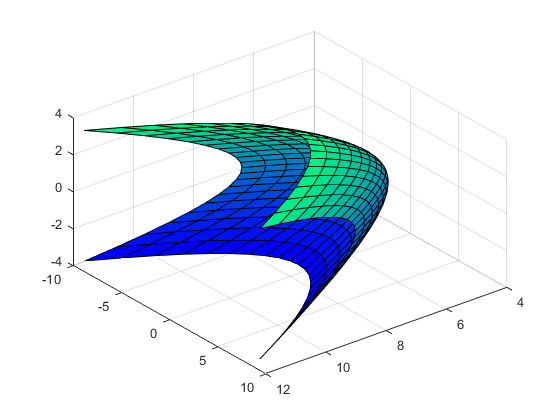

surf(x,y,z)
colormap winter
view([20,25,30])

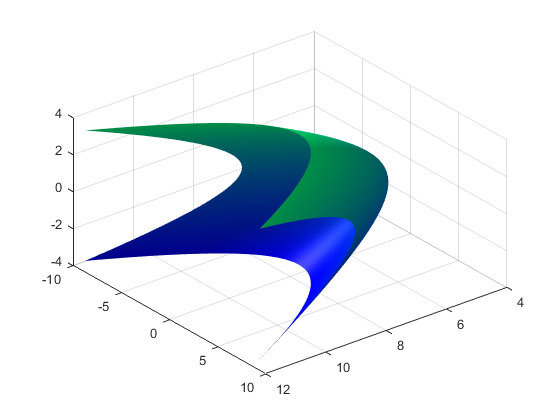

[u1,v1] = meshgrid(-1:0.01:1,-1:0.01:1);
x2 = interp2(u,v,x,u1,v1,'spline');
y2 = interp2(u,v,y,u1,v1,'spline');
z2 = interp2(u,v,z,u1,v1,'spline');
surfl(x2,y2,z2,'light')
colormap winter
shading interp
view([20,25,30])

Utilizzando dunque un interpolazione Spline su ognuna delle dimensioni si riesce ad avere una superfice più liscia e precisa.

# Smoothing

In questa sezione, saranno presentate le funzionalità del Matlab relative allo `Smoothing di Dati`. In particolare focalizzandoci su determinati risultati, verranno mostrati alcuni esempi nei quali le tecniche di interpolazione risultano utili nelll'analisi del  comportamento di un fenomeno, inoltre si può ottenere una stima dell'andamento al di fuori dell'intervallo dei dati. Infine descriviamo come queste tecniche sono adoperate nel miglioramento delle immagini.

## **Rapporto Occupazione-Popolazione**

Il rapporto tra occupazione e popolazione è la proporzione della popolazione di un paese che viene impiegata. L'occupazione è definita come persone in età lavorativa che, durante un  periodo di riferimento, sono state impegnate in attività per la produzione di beni o servizi per retribuzioni o profitti. Sono considetate persone in età lavorativa quelle da 15 anni in su. Il set di dati sul quale è stata effettuata l'analis è tratto dal sito web` data.worldbank.org. `Inizlamente si è utilizzata l'interpolazione lineare a tratti, da quest'ultima si nota che la variazione della percentuale di occupazione è di circa il 3%.

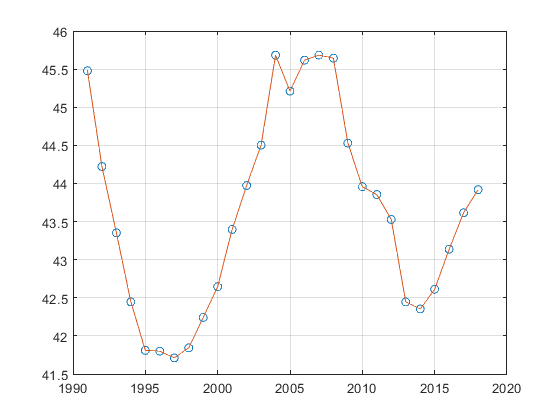

%importo i vettori nei quali ci sono i campioni estrapolati da analizzare
clear all
load Percentuale_occupati.mat 
t=1991:0.1:2018;
% Interpolazione Lineare a Tratti
z = interp1(anno,Percentuale_occupati,t);

plot(anno,Percentuale_occupati,'o',t,z)
grid

Valutiamone ora il comportamento applicando i vari metodi interpolanti.

%clear all
%anno=1991:1:2018;
%Percentuale_occupati=[45.47900009	44.22200012	43.35200119	 NaN	 NaN  NaN 	 NaN	 NaN	 NaN   NaN	43.39699936	43.97299957	44.50299835	45.68199921	45.2120018	45.61700058	45.68399811	45.64300156	44.52999878	43.95800018	43.85400009	43.52700043	42.44599915	42.35300064	42.61199951	43.13700104	43.61600113	43.91799927];
%save Percentuale_occupatiNAN anno Percentuale_occupati
c1 = polyfit(anno,Percentuale_occupati,1);
c2 = polyfit(anno,Percentuale_occupati,2);

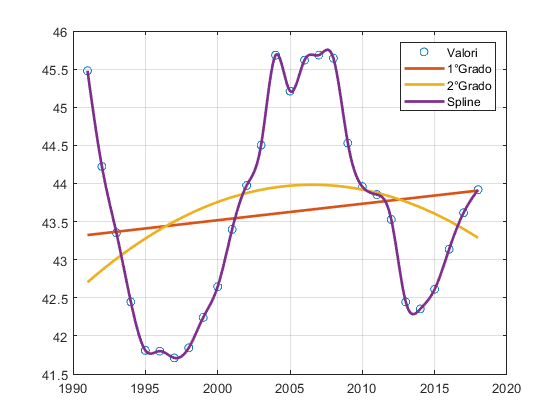

f1 = polyval(c1,t);
f2 = polyval(c2,t);
pp = csaps(anno,Percentuale_occupati,1);
ys1 = ppval(pp,t);
p = plot(anno,Percentuale_occupati,'o',t,f1,t,f2,t,ys1);
grid
legend('Valori','1°Grado','2°Grado','Spline')
p(4).LineWidth = 2; p(2).LineWidth = 2; p(3).LineWidth = 2;

Si osservi che il polinomio di `1°` e  `2°` grado non approssima minimamente la variazione delle percentuale nel corso degli anni. Infatti il `warning` ci mostra che il polinomio è  malcondizionato. In contrapposizione, l'andamento Spline è l'ideale mostrando esattamente il possibile andamento dei valori di occupazione. Si nota che la percentuale di occupazione è calata di circa l'`1.5%` dal 1991 al 2018.

## Previsione dell'andamento del fenomeno al di fuori dell'intervallo dei dati

Considerando il dataset precedente supponiamo di non avere a disposizione i campioni  per gli anni compresi tra 1994 e 2000. Si vuole dimostrare che è possibile prevedere l'andamento del tasso di occupazione per gli anni mancanti.

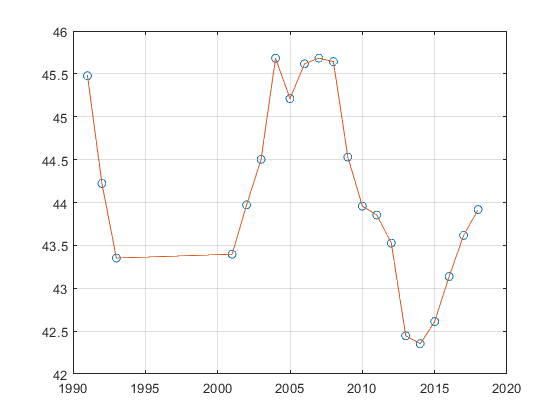

clear all
%anno=[1991:1:1993 , 2001:1:2018];
%Percentuale_occupati=[45.47900009	44.22200012	43.35200119	43.39699936	43.97299957	44.50299835	45.68199921	45.2120018	45.61700058	45.68399811	45.64300156	44.52999878	43.95800018	43.85400009	43.52700043	42.44599915	42.35300064	42.61199951	43.13700104	43.61600113	43.91799927];
%save Percentuale_occupatiNAN anno Percentuale_occupati
load Percentuale_occupatiNAN.mat 
t=1991:0.1:2018;
% Interpolazione Lineare a Tratti
z = interp1(anno,Percentuale_occupati,t);

plot(anno,Percentuale_occupati,'o',t,z)
grid

c1 = polyfit(anno,Percentuale_occupati,1);
c2 = polyfit(anno,Percentuale_occupati,2);

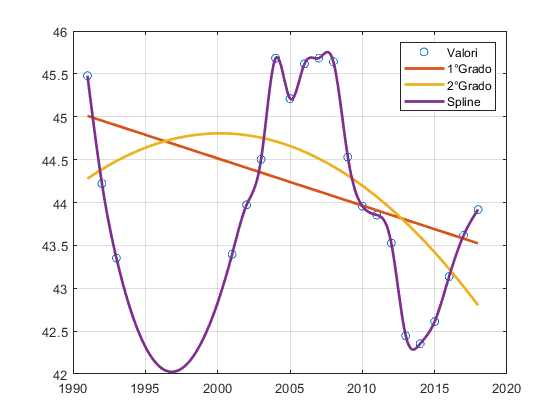

f1 = polyval(c1,t);
f2 = polyval(c2,t);
pp = csaps(anno,Percentuale_occupati,1);
ys1 = ppval(pp,t);
p = plot(anno,Percentuale_occupati,'o',t,f1,t,f2,t,ys1);
grid
legend('Valori','1°Grado','2°Grado','Spline')
p(4).LineWidth = 2; p(2).LineWidth = 2; p(3).LineWidth = 2;

Si nota che si riesce a determinare l'andamento approssimativo della curva anche per il periodo non noto, seppur con minor precisione ( da notare l'andamento nel 1995-1996).

## **Valutazione delle Performance dell'Algoritmo di PageRank**

In questo esempio mostriamo come le tecniche di smoothing sono adatte per misurare le` performance di un algoritmo`.Si  vuole stimare la complesstà dell'algoritmo di `Pagerank` .Si eseguono 1000 esecuzioni dell'algoritmo per dimensioni via via crescenti dell'input e se ne misura il tempo di esecuzione. Le misurazioni ottenute sono affette da errore, infatti ci posso essere dei picchi nelle misurazioni a causa di altri task che sta eseguendo il sistema operativo e dei relativi context switch necessari.

**Il modello di interpolazione utilizzato è quello del polinomio di secondo grado dei minimi quadrati**

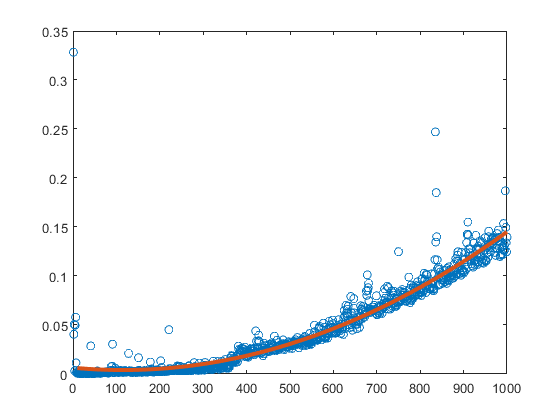

% Pulizia Workspace
clear all;
warning off;
 
N=1000;
T=zeros(1,N);
 
for i=1:N
     G = rand(i);
     G(G<0.7) = 0;
     G = sparse(logical(G));
     tic;
     PageRank(G);
     T(i)=toc;
end
x = linspace(1,N,N);
coef = polyfit(x,T,2);
t = 10:0.001:N;
fx = polyval(coef,t);
p = plot(x,T,'o',t,fx);
p(2).LineWidth = 3;

warning on;

Il polinomio mostra come l'andamento dei tempi di esecuzione dell'algoritmo cresce man mano che aumenta il numero di iterazioni effettuate. Il metodo di interpolazione utilizzato minimizza gli errori di misurazione restituendo una curva che è un approssimazione corretta della curva che descrive la complessità dell'algoritmo.

## **Tool per lo Smoothing delle Immagini**

Come già anticipato, lo smoothing risulta molto utile quando si vuole migliorare la qualità di un immagine. E' stato realizzato un tool apposito che permette di caricare un immagine e di effettuare lo Smoothing confrontando ` il metodo interpolante lineare` con quello` spline`. Inoltre e' possibile effettuare uno `zoom` immagine per ottenere una migliore visualizzazione dell'effetto prodotto tramite lo Smoothing.

Per eseguire il tool, bisogna digitare nella Command Line del MATLAB il comando `GUI_Image_Smoothing`

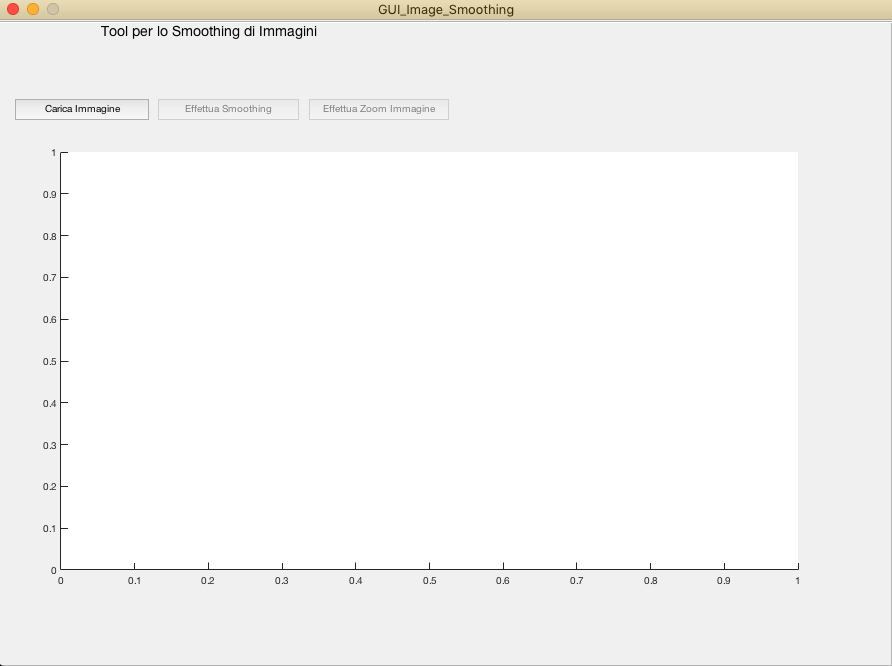

Il tool presenta:

- Un asse coordinato utilizzato per mostrare le immagini secondo la loro scala di pixel

- Un pulsante `Carica Immagine` che una volta cliccato permette di selezionare l'immagine in formato ".jpg .gif .png" , di conseguenza selezionata l'immagine abilita i pulsanti` Effettua Smoothing` e `Effettua Zoom Immagine`

- Il pulsante `Effettua Smoothing` che mostra le caratteristiche dello Smoothing

- Il pulsante `Effettua Zoom Immagine `che mostra le caratteristiche dello Smoothing ancora di più nel dettaglio

Di seguito mostriamo alcuni esempi di utilizzo del tool.

- Click su `Carica Immagine`

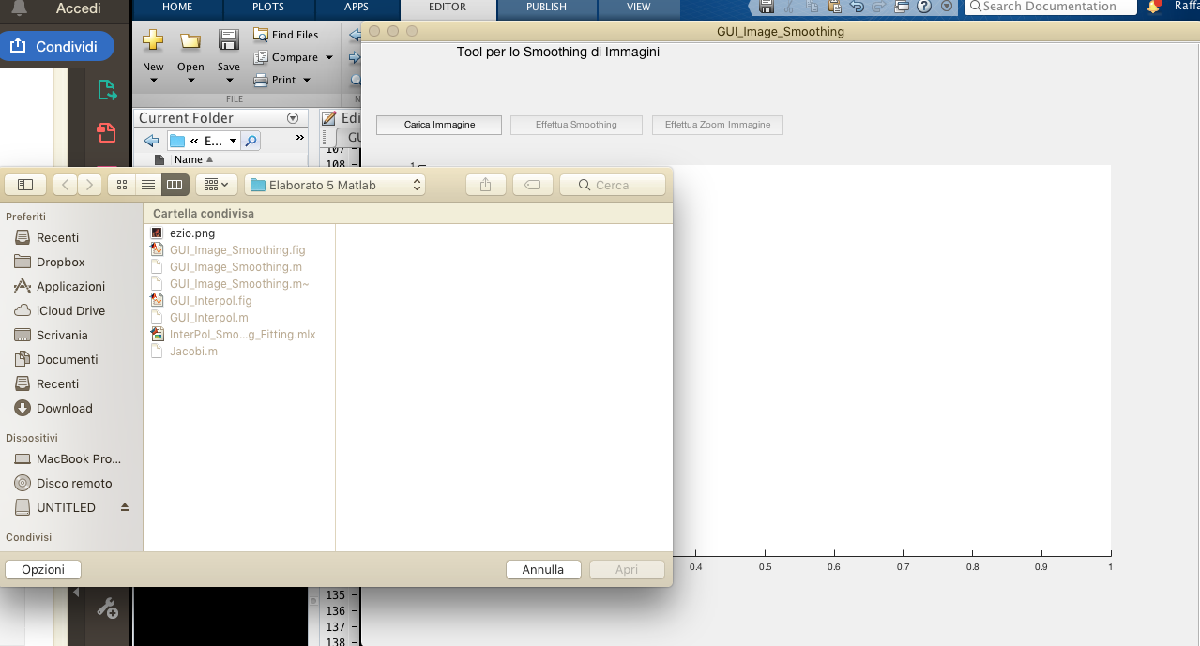

- Click su `Effettua Smoothing`

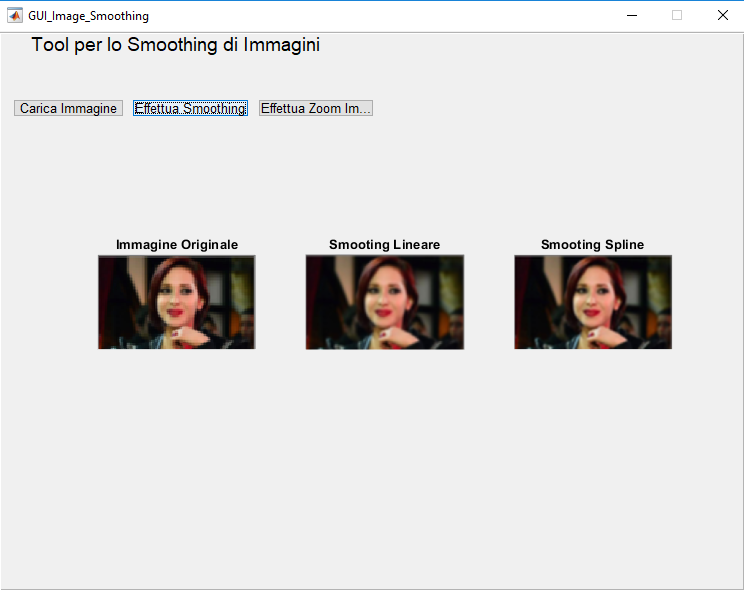

- Click su `Effettua Zoom Immagine`

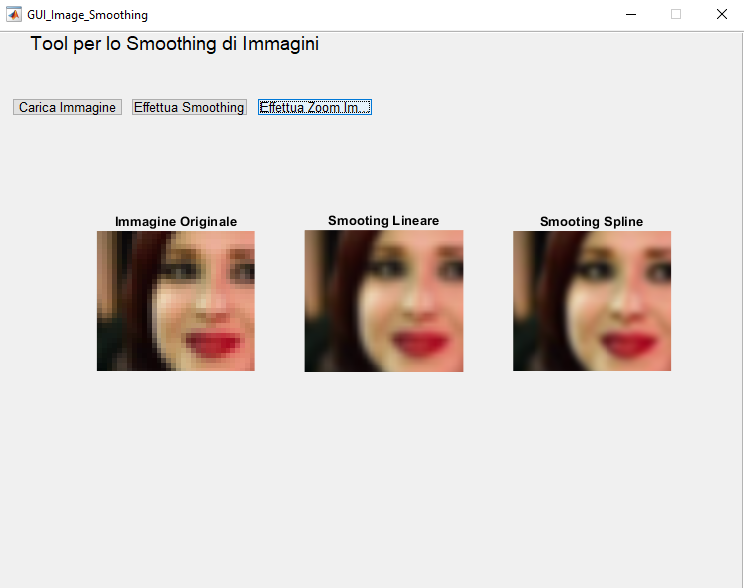

Si nota il netto miglioramento dell'immagine.

Viene mostrato un ulteriore esempio che mostra il miglioramento di un immagine rappresentante un paesaggio.

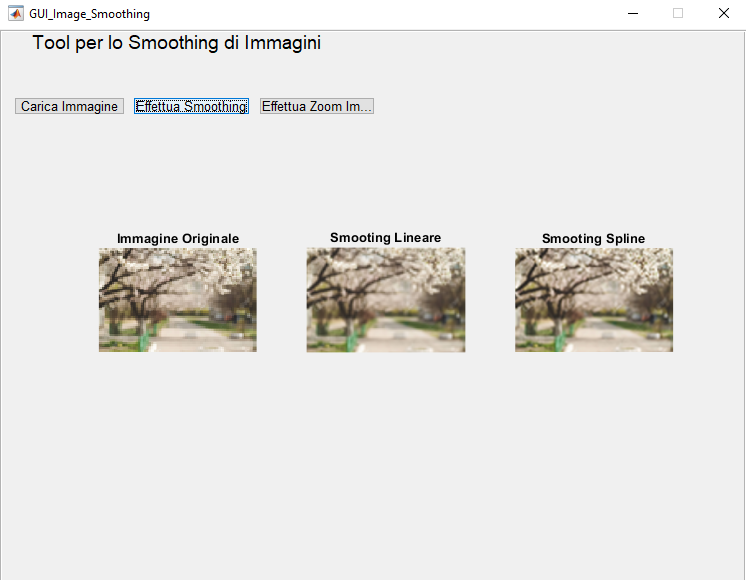

## Riferimenti

- *Econometrics Toolbox, *[*https://it.mathworks.com/help/econ/data-sets-and-examples.html*](https://it.mathworks.com/help/econ/data-sets-and-examples.html)

- *Wikipedia - Paraboloide Ellittico, *[*Wikipedia : Paraboloide Ellittico*](https://it.wikipedia.org/wiki/Paraboloide)

- *Soccer Statistics, WhoScored, *[*https://www.whoscored.com/Statistics*](https://www.whoscored.com/Statistics)

- *MATLAB Gui, *[*https://it.mathworks.com/discovery/matlab-gui.html*](https://it.mathworks.com/discovery/matlab-gui.html)

- [*Docenti.unina.it D'alessio Alessandra*](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

## Autori

***Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936***